% =========================================================================
% 轨迹生成脚本：笛卡尔空间直线规划 (Cartesian Straight Line)
% 目标：末端执行器沿着 3D 空间直线移动
% =========================================================================
clear; clc; close all;

%% 1. 定义起止点坐标 (单位: m)
% 建议：Y 轴错开一点，避免奇异点
start_pos = [0.15, 0.0, 0.1]; % 起点 (x, y, z)
end_pos   = [0.3,  0.5, 0.4]; % 终点

%% 2. 检查起点和终点是否在工作空间内
try
    q_start_check = inverse_kinematics(start_pos(1), start_pos(2), start_pos(3));
    q_end_check   = inverse_kinematics(end_pos(1),   end_pos(2),   end_pos(3));
    fprintf('起止点逆解检查通过。\n');
catch ME
    error('错误：起点或终点超出机械臂工作空间！\n%s', ME.message);
end

起止点逆解检查通过。



%% 3. 生成时间序列
T = 2.0;       % 运动总时间
dt = 0.0001;   % 控制周期 (0.1ms)
t_vec = 0:dt:T;
num_steps = length(t_vec);

%% 4. 笛卡尔空间直线插值
% 我们不直接插值角度，而是插值 XYZ 坐标
% 使用五次多项式生成一个 0 到 1 的平滑缩放因子 s(t)
% s=0 (起点), s=1 (终点)

s = zeros(1, num_steps);   % 位置缩放因子
ds = zeros(1, num_steps);  % 速度缩放因子
dds = zeros(1, num_steps); % 加速度缩放因子

for i = 1:num_steps
    tau = t_vec(i) / T;
    if tau > 1, tau = 1; end
    
    % 五次多项式规划 (归一化)
    s(i)   = 10*tau^3 - 15*tau^4 + 6*tau^5;
    % 对时间 t 求导需要除以 T
    ds(i)  = (30*tau^2 - 60*tau^3 + 30*tau^4) / T; 
    dds(i) = (60*tau - 180*tau^2 + 120*tau^3) / (T^2);
end

% 生成笛卡尔空间轨迹 P(t) = P_start + s(t) * (P_end - P_start)
% pos_traj: [3 x N]
pos_traj = start_pos(:) + (end_pos(:) - start_pos(:)) * s;

%% 5. 逐点逆解 (Inverse Kinematics Loop)
% 将直线上的每一个点转换为关节角度
q_traj = zeros(3, num_steps);

fprintf('正在计算路径点逆解 (共 %d 点)...\n', num_steps);

正在计算路径点逆解 (共 20001 点)...


for i = 1:num_steps
    x_curr = pos_traj(1, i);
    y_curr = pos_traj(2, i);
    z_curr = pos_traj(3, i);
    
    try
        q_traj(:, i) = inverse_kinematics(x_curr, y_curr, z_curr);
    catch
        error('在路径中间点 (%.2f, %.2f, %.2f) 处逆解失败！可能是路径经过了奇异点或超出范围。', ...
            x_curr, y_curr, z_curr);
    end
end

%% 6. 计算关节速度和加速度 (数值微分)
% 因为 q 是非线性变化的，我们直接对 q_traj 进行微分求 dq 和 ddq
% 使用 gradient 函数保持数组长度不变

dq_traj = zeros(3, num_steps);
ddq_traj = zeros(3, num_steps);

for k = 1:3
    % 一阶导数 (速度)
    dq_traj(k, :) = gradient(q_traj(k, :), dt);
    % 二阶导数 (加速度)
    ddq_traj(k, :) = gradient(dq_traj(k, :), dt);
end

%% 7. 转换为 Simulink 格式
ts_q   = timeseries(q_traj.', t_vec);
ts_dq  = timeseries(dq_traj.', t_vec);
ts_ddq = timeseries(ddq_traj.', t_vec);

fprintf('直线轨迹生成完毕！\n');

直线轨迹生成完毕！


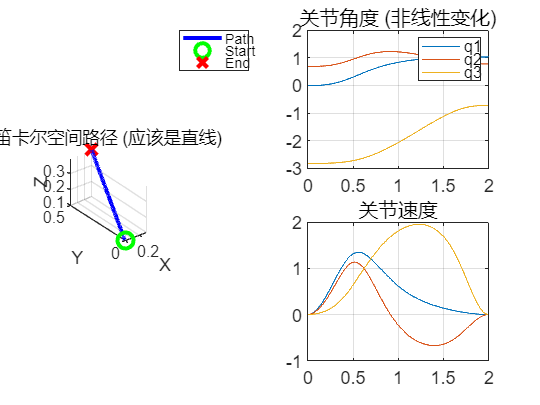


%% 8. 同步初始状态
x0_robot = [q_traj(:,1); 0; 0; 0]; 
assignin('base', 'x0_robot', x0_robot);

%% 9. 绘图验证
figure('Color', 'w', 'Name', '直线轨迹验证');

% 图1: 3D 路径
subplot(2,2,[1 3]); 
plot3(pos_traj(1,:), pos_traj(2,:), pos_traj(3,:), 'b-', 'LineWidth', 2); hold on;
plot3(start_pos(1), start_pos(2), start_pos(3), 'go', 'MarkerSize', 8, 'LineWidth', 2);
plot3(end_pos(1), end_pos(2), end_pos(3), 'rx', 'MarkerSize', 8, 'LineWidth', 2);
grid on; axis equal; view(3);
xlabel('X'); ylabel('Y'); zlabel('Z');
title('笛卡尔空间路径 (应该是直线)');
legend('Path', 'Start', 'End');

% 图2: 关节角度变化
subplot(2,2,2);
plot(t_vec, q_traj); grid on;
title('关节角度 (非线性变化)'); legend('q1','q2','q3');

% 图3: 关节速度
subplot(2,2,4);
plot(t_vec, dq_traj); grid on;
title('关节速度');


% =========================================================================
% 局部函数: 逆运动学 (保持不变)
% =========================================================================

function q = inverse_kinematics(x, y, z)
    d1 = 0.1; a2 = 0.4; a3 = 0.3;

    % 1. 关节 1
    q1 = atan2(y, x);

    % 2. 几何准备
    r = sqrt(x^2 + y^2);
    z_eff = z - d1;
    D_sq = r^2 + z_eff^2;
    
    % 3. 关节 3 (Elbow Up)
    cos_q3 = (D_sq - a2^2 - a3^2) / (2 * a2 * a3);
    cos_q3 = max(min(cos_q3, 1), -1);
    q3 = -acos(cos_q3); 

    % 4. 关节 2
    alpha = atan2(z_eff, r);
    k1 = a2 + a3 * cos(q3);
    k2 = a3 * sin(q3);
    q2 = alpha - atan2(k2, k1);

    q = [q1; q2; q3];
end